# Invasion Fitness under Constant Selection (Figures)

This is a companion file that generates interesting figures. 

## Initialize

clear; clc; % clear stored variables
close all % closes open figures

## Local Mutation Kernel

Here we define the local mutation kernel, which govens how offspring mutate for a given mutation rate $u$. 

This also defines $Q(u)$, given by how mutation beyond the boundaries is handled. The code for this is given in functions defined at the end of the file (as Matlab requires for local functions). 

To better visualize this, some rows of $Q(u)$ are plotted. 

normal = @(xs, strat, u) normpdf(xs,strat,u); %exp(((xs-mean)/sigma).^2/2)/(sigma*sqrt(2*pi));
peak   = @(xs, strat, u) interp1([-10, strat-u/2, strat, strat+u/2, 10], [0, 0, 1, 0, 0], xs);
flat   = @(xs, strat, u) double(abs(xs-strat) < u/2);

## Fitness

Here we define the fitness we want to investigate. 

To help visualize this, a plot is given, though not with the true discretization. 

Some options: 

min_fit, sin_fit, cos_fit, 

twin_steps_funct(w,g,h), three_steps_funct(w,d,h), centered_two_steps_funct(w1,h1,w2,h2), peak_and_shoulders(ph, pw, vw, sh)

rand_fit_1(n_pts), and generic is @(strats) XXX.

indic = @(x,a,b) x>a && x<b;

min_fit     = @(strats) 1+min(strats, 1-strats);
sin_fit     = @(strats) 2+sin(2*pi*(strats));
cos_fit     = @(strats) 2+cos(2*pi*strats);
scrunch_sin = @(strats) arrayfun(@(x) 2+sin(6*pi*x*indic(x,1/3,2/3)), strats);
two_steps   = @(strats) arrayfun(@(x) 1+2*indic(x,0,0.2)+2.2*indic(x,1-0.025,1), strats);

twin_steps_funct = @(w,g,h) @(strats) arrayfun(@(x) ...
    1+(h-1)*indic(x,1/2-g/2-w,1/2-g/2)+(h-1)*indic(x,1/2+g/2,1/2+g/2+w), strats);
twin_steps = @(strats) twin_steps_funct(0.2, 0.4, 2, strats); % in circ?

three_steps_funct = @(w,d,h) @(strats) arrayfun(@(x) 1 + (h-1)*indic(x,0.5-d-3*w,0.5-d-w) + ...
    1*indic(x,0.5-w,0.5+w) + (h-1)*indic(x,0.5+d+w,0.5+d+3*w), strats);
three_steps = @(strats) three_steps_funct(0.1, 0.05, 1.9, strats);

centered_two_steps_funct = @(w1,h1,w2,h2) @(strats) arrayfun(@(x) ...
    1 + h1*indic(x,(1-w1-w2)/3, (1-w1-w2)/3+w1) + ...
    h2*indic(x,1-(1-w1-w2)/3-w2, 1-(1-w1-w2)/3), strats);
centered_two_steps = centered_two_steps_funct(0.2,3,0.025,3.2);

peak_and_shoulders = @(ph, pw, vw, sh) @(strats) arrayfun(@(x) ...
    sh+(ph-1)*indic(x,0.5-pw/2, 0.5+pw/2)+(1-sh)*indic(x,0.5-pw/2-vw, 0.5+pw/2+vw), strats);
foo = @(strats) peak_and_shoulders(1.51,0.1,0.05,1.5,strats);

% not functions, so they don't change each time fitness is called
rand_fit_1 = @(n_pts) @(strats) 1+interp1(linspace(0,1,n_pts),rand(1,n_pts), strats); 
rand_fit_2 = @(n_pts) @(strats) 1+interp1([0, sort(rand(1,n_pts-2)), 1], rand(1,n_pts), strats); 

%load('increasing with MR')
%fitness = @(t,dist) interp1(linspace(0,1,51), ...
%    fitness_leading_to_increasing_curve, strats);

## Apparent local max

Seems to be an artifact of n_strats. Might not even hold on a finite grid, as using a better approximation of $Q(u)$ makes it vanish. 

n_strats = 101;
us = 0.001*(1:30);
fitness = sin_fit;

figure
plot(linspace(0,1,n_strats),fitness(linspace(0,1,n_strats)),'k')
title("Fitness")
drawnow

spread_matrix_funct = @(u,n_strats) accum_spread_matrix(u, normal, n_strats);
tic
[max_eigs, stable_dists] = compute_max_eigs(fitness, spread_matrix_funct, us, n_strats);
toc

Elapsed time is 0.284150 seconds.



figure
plot(us, max_eigs)
title("Max Eig vs MR")
drawnow

figure
hold on
is = 10:15;
for j=1:length(is)
    plot(linspace(0,1,n_strats), stable_dists(is(j),:))
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off
drawnow

ns = [101, 251, 501];
max_eigs_record = zeros(length(ns), length(us));
for i=1:length(ns)
    tic
    [max_eigs, ~] = compute_max_eigs(fitness, spread_matrix_funct, us, ns(i));
    max_eigs_record(i,:) = max_eigs;
    toc
end

Elapsed time is 0.404746 seconds.
Elapsed time is 2.480344 seconds.
Elapsed time is 9.538265 seconds.


figure
hold on
for i=1:length(ns)
    plot(us, max_eigs_record(i,:))
end
title("Max Eig vs MR for various n strats")
legend(arrayfun(@(u) num2str(u), ns, 'UniformOutput', false))
hold off
drawnow

tic
[max_eigs, ~] = compute_max_eigs(fitness, ...
    @(u,n_strats) integ_accum_spread_matrix(u, normal, n_strats), us, n_strats);
toc
figure
plot(us,max_eigs)
title("Max Eigs vs MR, using integ accum")

Here we see that using a better approximation of $Q(u)$ eliminates this effect. 

## Same thing in circ

fitness = twin_steps_funct(0.25,0.25,2);
spread_matrix_funct = @(u,n_strats) circ_spread_matrix(u, normal, n_strats);

figure
plot(linspace(0,1,n_strats),fitness(linspace(0,1,n_strats)),'k')
title("Fitness")
drawnow

n_strats = 401;
us = 0.0025*(1:10);
tic
[max_eigs, stable_dists] =  compute_max_eigs(fitness,spread_matrix_funct,us,n_strats);
toc

Elapsed time is 1.952113 seconds.


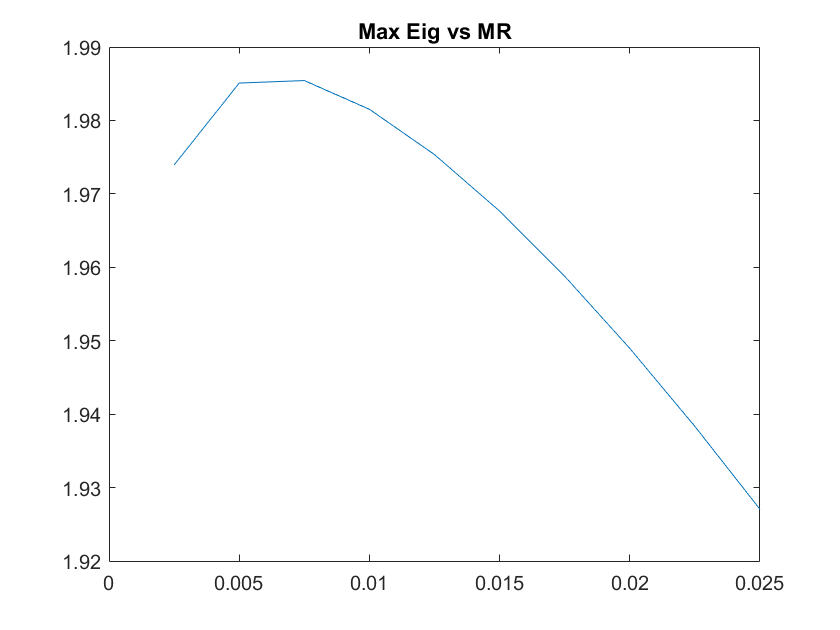


figure
plot(us, max_eigs)
title("Max Eig vs MR")

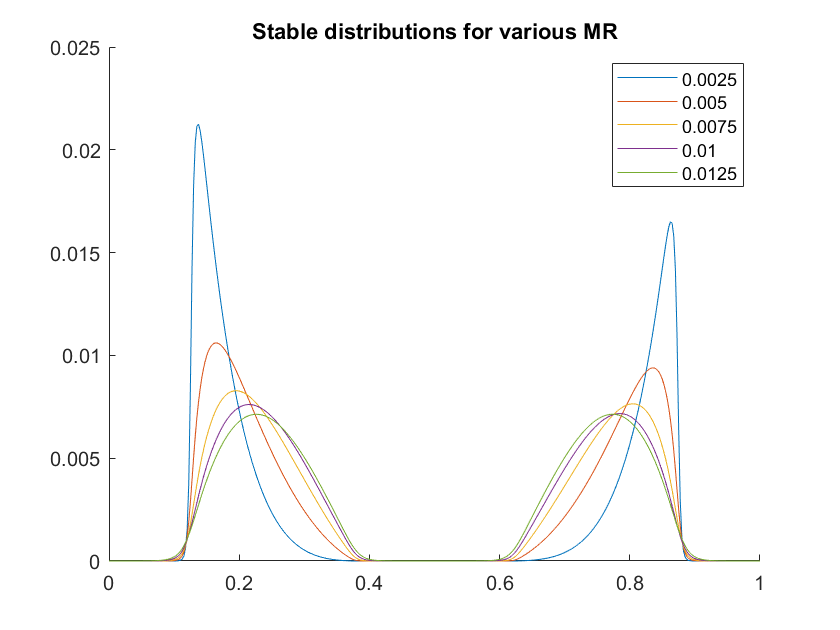

drawnow

figure
hold on
is = 1:5;
for j=1:length(is)
    plot(linspace(0,1,n_strats), stable_dists(is(j),:))
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

drawnow

ns = [101, 251, 501, 751, 1001];
max_eigs_record = zeros(length(ns), 10);
for i=1:length(ns)
    tic
    [max_eigs, ~] =  compute_max_eigs(fitness,spread_matrix_funct,us,ns(i));
    max_eigs_record(i,:) = max_eigs;
    toc
end

Elapsed time is 0.084959 seconds.
Elapsed time is 0.538946 seconds.
Elapsed time is 2.412853 seconds.
Elapsed time is 8.021458 seconds.
Elapsed time is 16.633512 seconds.


figure
hold on
for i=1:length(ns)
    plot(us, max_eigs_record(i,:))
end

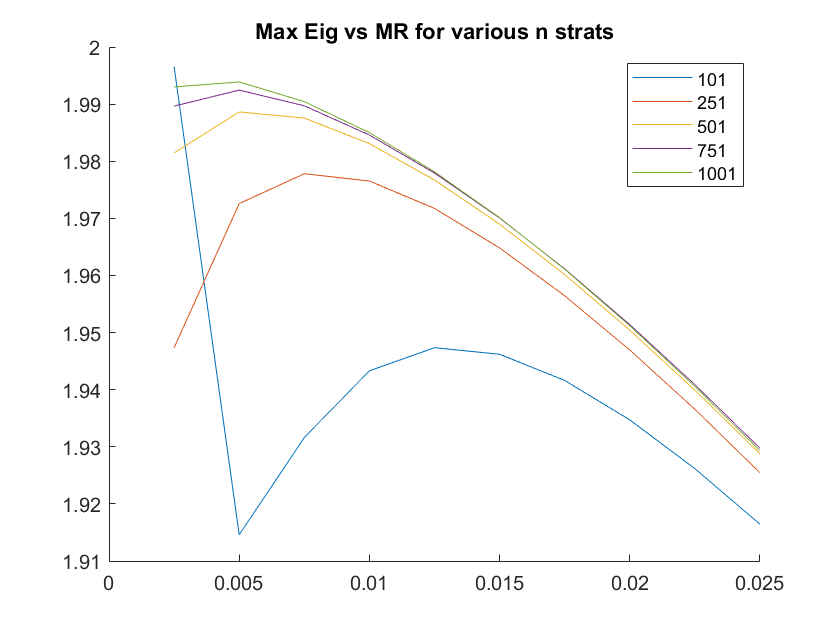

title("Max Eig vs MR for various n strats")
legend(arrayfun(@(u) num2str(u), ns, 'UniformOutput', false))
hold off

The same improvement to $Q(u)$ is likely to eliminate this too. 

## Odd behavior for flat_spread

It seems like this results from a different number of points being included in row, despite the kernels being the same. 

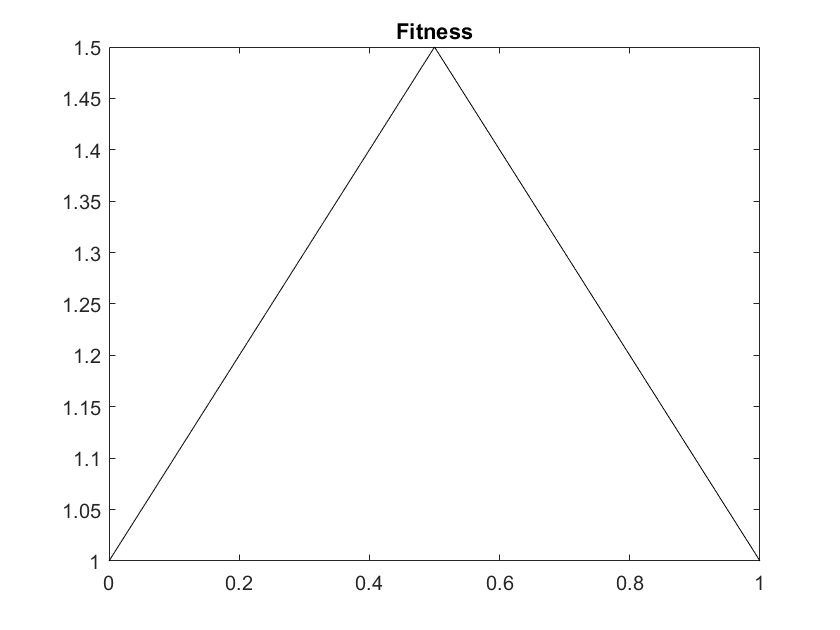

fitness = min_fit;
spread_matrix_funct = @(u,n_strats) circ_spread_matrix(u, flat, n_strats);

figure
plot(linspace(0,1,101),fitness(linspace(0,1,101)),'k')
title("Fitness")

drawnow

ns = 1+100*(1:5);
max_eigs_record = zeros(length(ns), length(us));
for i=1:length(ns)
    tic
    [max_eigs, ~] = compute_max_eigs(fitness, spread_matrix_funct, us, ns(i));
    max_eigs_record(i,:) = max_eigs;
    toc
end

Elapsed time is 0.650173 seconds.
Elapsed time is 3.340292 seconds.
Elapsed time is 5.786315 seconds.
Elapsed time is 11.408251 seconds.
Elapsed time is 18.163575 seconds.


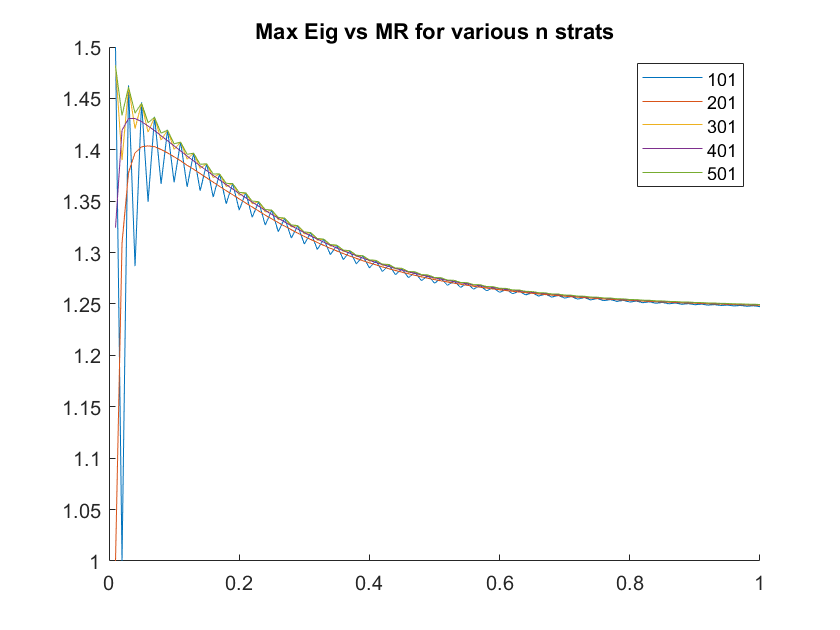

figure
hold on
for i=1:length(ns)
    plot(us, max_eigs_record(i,:))
end
title("Max Eig vs MR for various n strats")
legend(arrayfun(@(u) num2str(u), ns, 'UniformOutput', false))
hold off

## Increasing at end, in trunc / accum

Seems like a boundary effect, as this doesn't occur in the circle, is more pronounced in accum. 

Maybe the explanation is that the traits nearer to the end spread more towards the center then towards the boundary. Futher, the endpoints only have contribution from one side, whereas the center has from the left and right. 

For n_strats = 3, flat spread, this can be verified analytically (simple 3x3 matrix). 

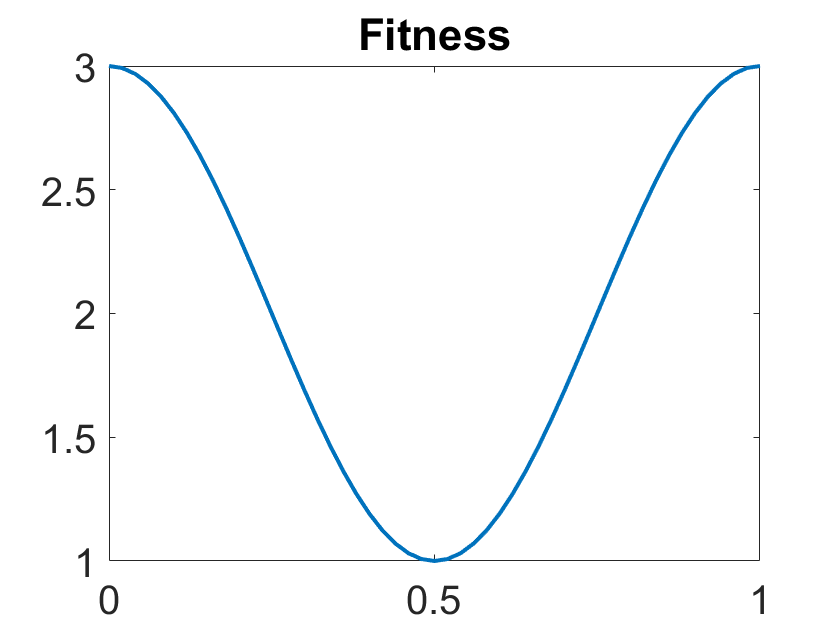

fitness = cos_fit;

figure
plot(linspace(0,1,51), fitness(linspace(0,1,51)), 'LineWidth', 2)
set(gca,"FontSize",20)
title("Fitness")

drawnow

n_strats = 51;
strats = linspace(0,1,n_strats);
us = 0.025*(1:40);
tic
[max_eigs, stable_dists] =  compute_max_eigs(fitness, ...
    @(u,n_strats) integ_trunc_spread_matrix(u, normal, n_strats), us, n_strats);
toc

Elapsed time is 20.701912 seconds.


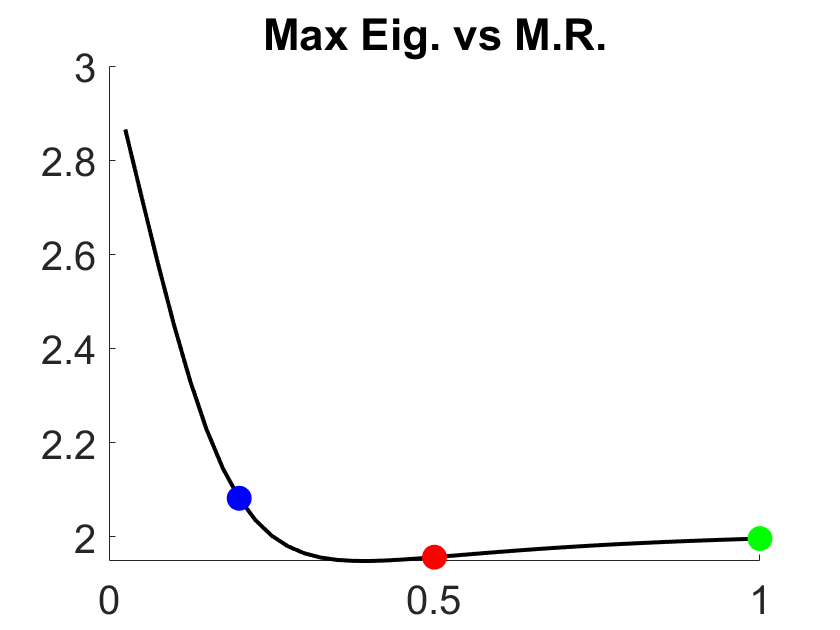


figure
%subplot(1,2,1)
hold on
plot(us, max_eigs, '-k', 'LineWidth', 2)
%plot([0.2, 0.5, 1], [max_eigs(8), max_eigs(20), max_eigs(40)], 'o')
plot(0.2, max_eigs(8), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 12)
plot(0.5, max_eigs(20), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 12)
plot(1, max_eigs(40), 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 12)
set(gca,"FontSize",20)
hold off
title("Max Eig. vs M.R.")

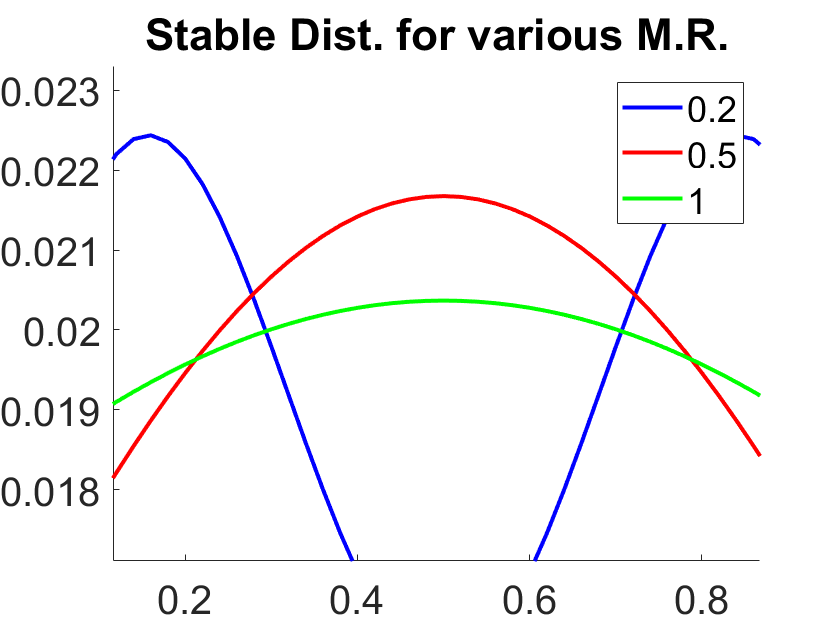

%title('\textbf{$$\lambda_{\max}(Q(u)F)$$ vs u}','interpreter','latex')
%title("Max Eig vs MR")

figure
%subplot(1,2,2)
hold on
is = [8, 20, 40];
plot(strats, stable_dists(8,:), 'b', 'LineWidth', 2) % -
plot(strats, stable_dists(20,:), 'r', 'LineWidth', 2) % --
plot(strats, stable_dists(40,:), 'g', 'LineWidth', 2) % -.
%title(["Stable distributions,","various M.R."])
title(["Stable Dist. for various M.R."])
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
set(gca,"FontSize",20)
hold off

One can try to create this same effect by somehow simulating the boundary, e.g. by having a large drop off. Using the circle eliminates boundary effects. I don't think this technique would work for an unbounded domain, as it is based on a finite number of traits. One could also simulate an unbounded domain by compressing the fitness function into a small region, say around 0.5. 

## Same in circ, though far weaker

seems robust to modifying n_strats / var of fitness function. It happens for a large MR, so maybe isn't a discretization issue. 

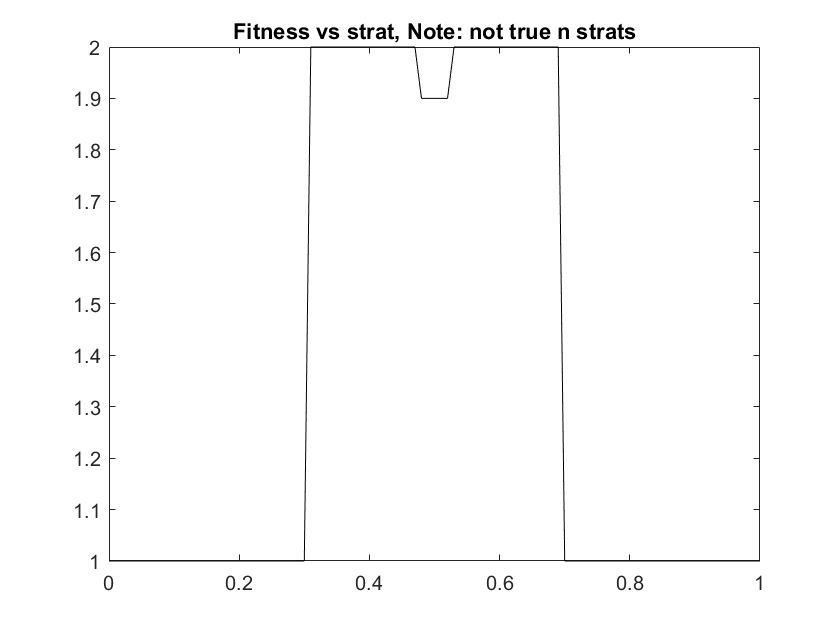

h = 2; w = 0.4; dip = 0.1; dip_width = 0.05;
fitness = @(strats) arrayfun(@(x) 1 + (h-1)*indic(x,1/2-w/2,1/2+w/2) - ...
    dip*indic(x,1/2-dip_width/2,1/2+dip_width/2), strats);

test_n = 101;
figure
plot(linspace(0,1,test_n), fitness(linspace(0,1,test_n)), 'k')
title("Fitness vs strat, Note: not true n strats")


n_strats = 501;
strats = linspace(0,1,n_strats);

us = 0.5+0.02*(1:15);

tic 
[max_eigs, stable_dists] =  compute_max_eigs(fitness,...
    @(u,n_strats) circ_spread_matrix(u, normal, n_strats), us, n_strats);
toc

Elapsed time is 4.264787 seconds.


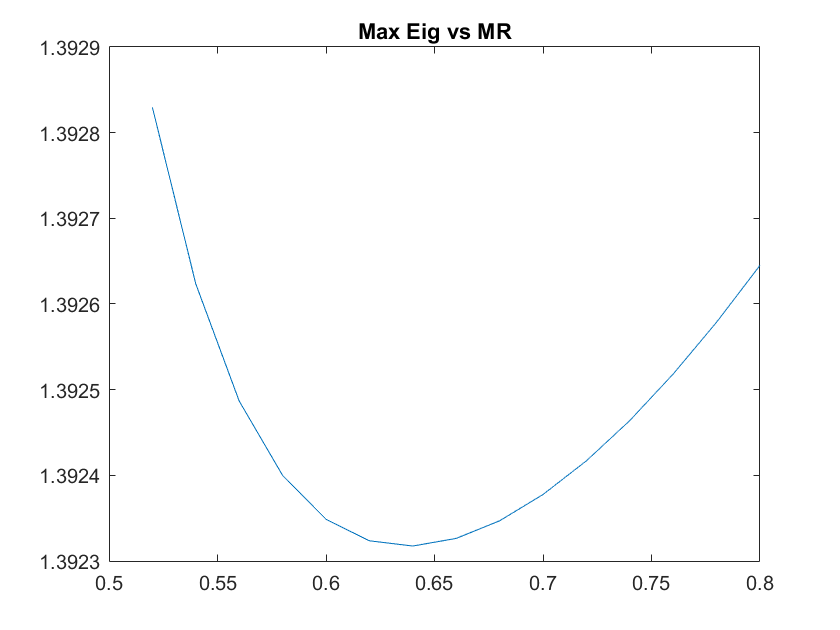

figure
plot(us, max_eigs)
title("Max Eig vs MR")

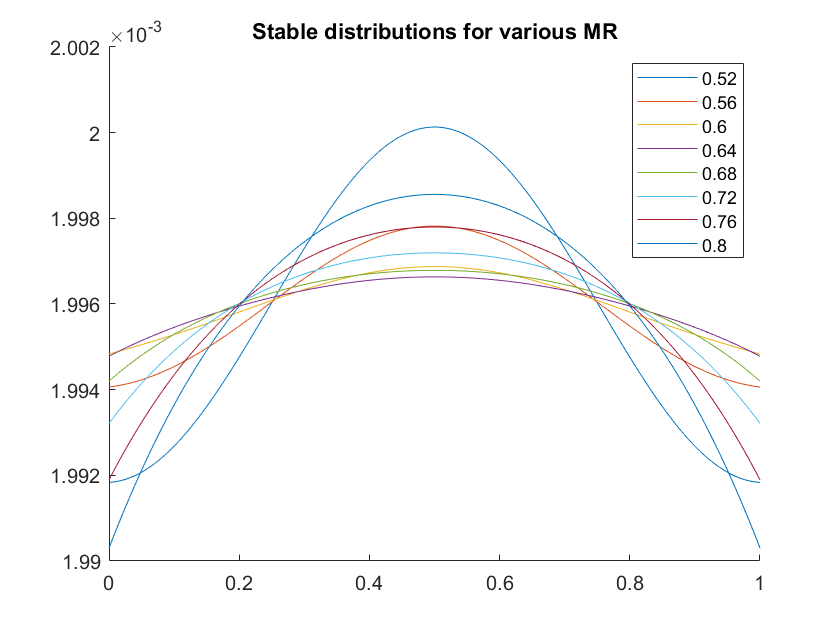


figure
hold on
n_plot = 8;
is = floor((1:n_plot)*length(us)/n_plot);
for i=1:length(is)
    plot(strats, stable_dists(is(i),:));
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

[a,b] = min(max_eigs)

a = 1.3923

b = 7

max_eigs(end)

ans = 1.3926

nnz(arrayfun(@(i) max_eigs(i+1) > max_eigs(i), 1:(length(us)-1)))

ans = 8

Note that the distributions are fairly flat / nonzero at the boundaries, so this does not model an unbounded domain. 

## Another example

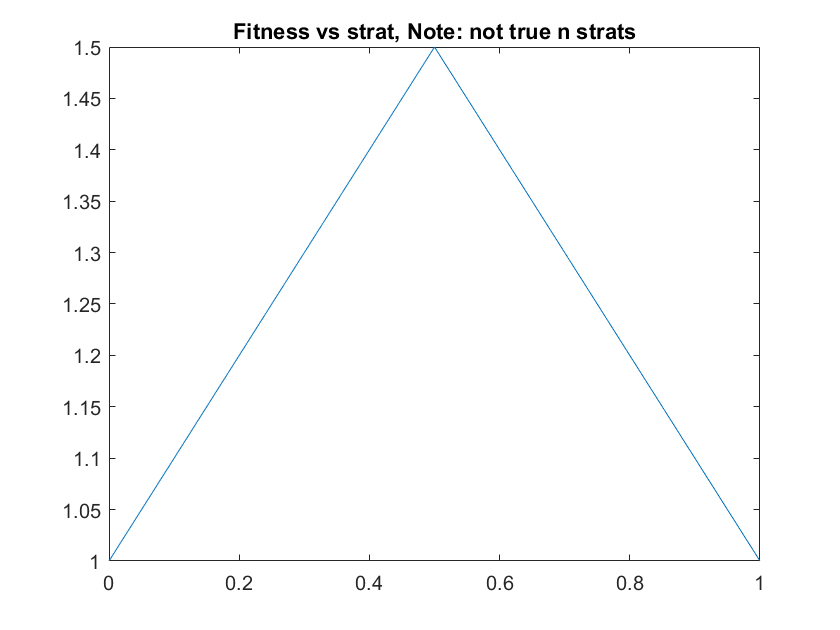

fitness = min_fit;

test_n = 101;
figure
plot(linspace(0,1,test_n), fitness(linspace(0,1,test_n)))
title("Fitness vs strat, Note: not true n strats")


n_strats = 101;
strats = linspace(0,1,n_strats);
us = 0.01*(1:100);
tic
%[max_eigs, stable_dists] =  compute_max_eigs(@(strats) 1+min(strats, 1-strats), ...
[max_eigs, stable_dists] =  compute_max_eigs(fitness, ...
    @(u,n_strats) circ_spread_matrix(u, normal, n_strats), us, n_strats);
toc

Elapsed time is 1.760555 seconds.


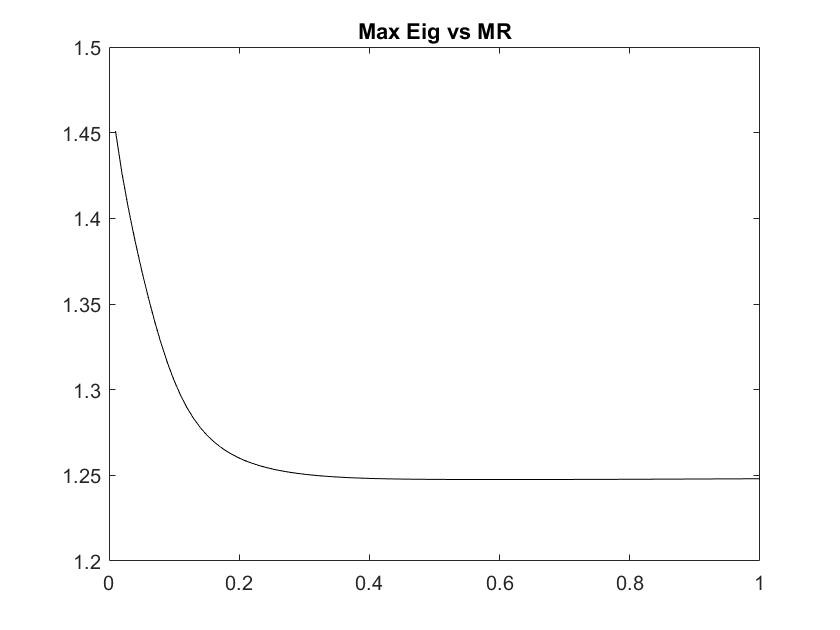


figure
plot(us, max_eigs, '-k')
title("Max Eig vs MR")

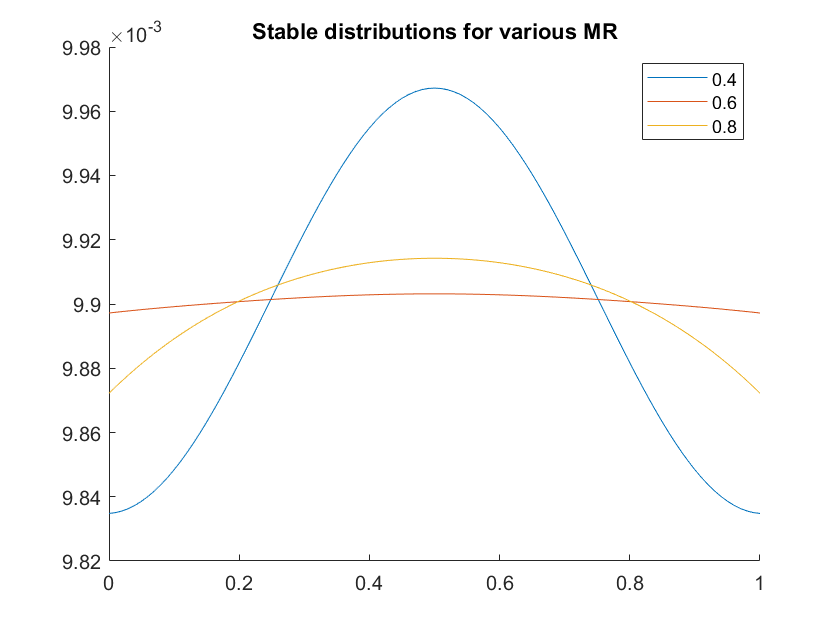


figure
hold on
is = [40, 60, 80];%floor(0.2*(1:5)*length(us));
for i=1:length(is)
    plot(strats, stable_dists(is(i),:));
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

[a,b] = min(max_eigs)

a = 1.2476

b = 60

max_eigs(end)

ans = 1.2480

The fact that it holds here too suggests this might occur in all functions. Not always (below MR = 1), but was around 0.6 in 3 of 5 trials. 

## Wraparound effect, MR > 1 in circ with flat kernel

This effect isn't as strong for normal or peak kernel, but still seems to hold. Also seems to hold for large n. This makes some sense, as for large MR, the flat spread functions wrap around and end up looking like a indicator function around the OPPOSITE strategy.

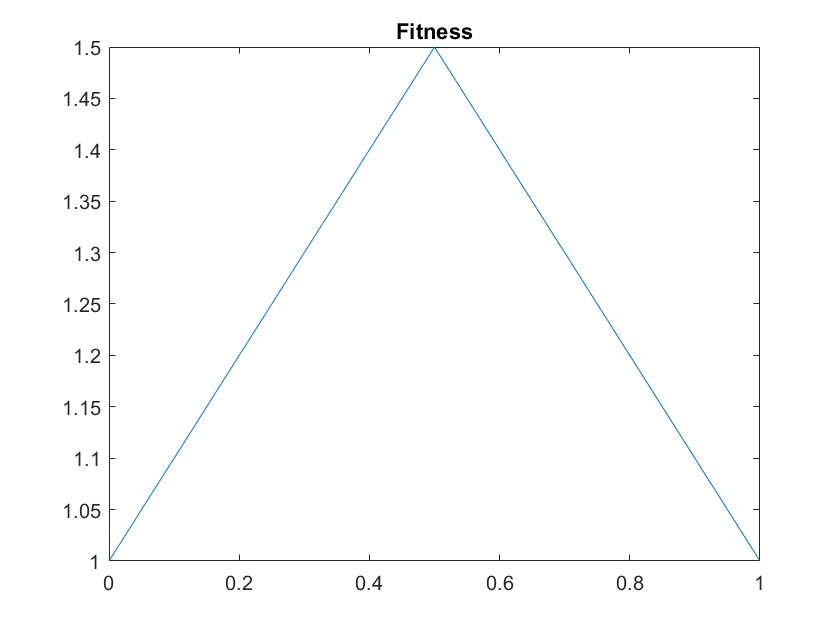

fitness = min_fit;
figure
plot(linspace(0,1,101),fitness(linspace(0,1,101)))
title("Fitness")

drawnow

n_strats = 501;
strats = linspace(0,1,n_strats);
us = 0.5+0.1*(1:30);
tic
[max_eigs, stable_dists] =  compute_max_eigs(fitness, ...
    @(u,n_strats) circ_spread_matrix(u, flat, n_strats), us, n_strats);
toc

Elapsed time is 7.211714 seconds.


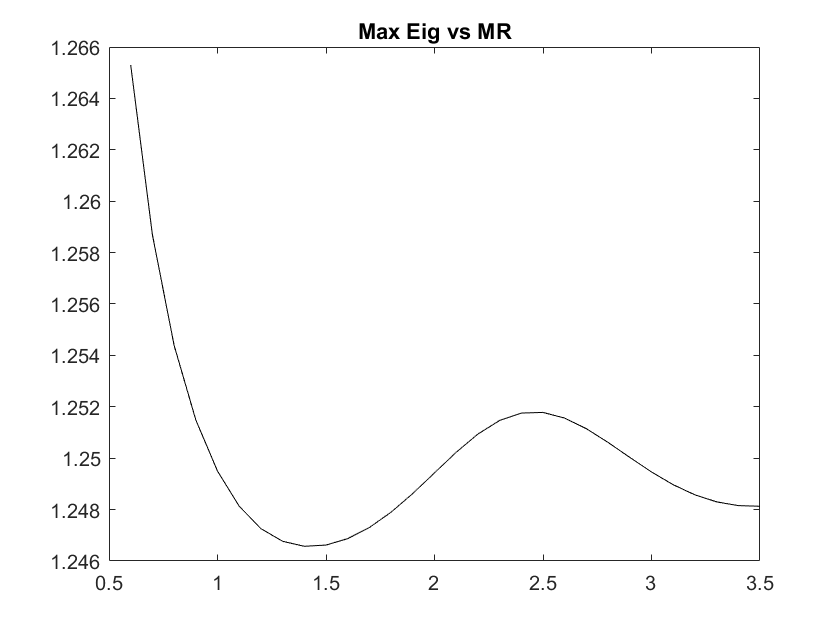


figure
plot(us, max_eigs, '-k')
title("Max Eig vs MR")

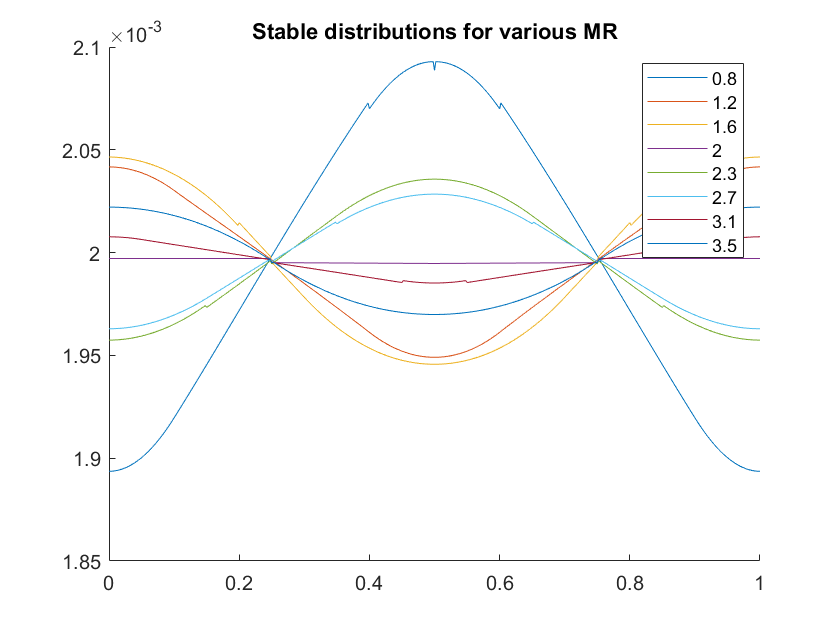


figure
hold on
n_plot = 8;
is = floor((1:n_plot)*length(us)/n_plot);
for i=1:length(is)
    plot(strats, stable_dists(is(i),:));
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

## Confirming this effect, and higher frequency demonstration.

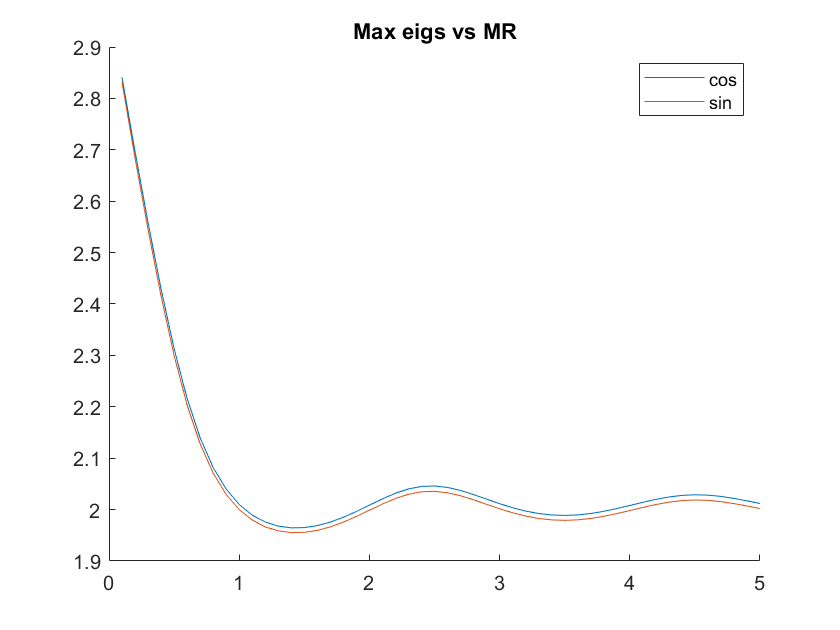

n_strats = 101;
strats = linspace(0,1,n_strats);
us = 0.1*(1:50);
tic
[max_eigs_cos, stable_dists_cos] =  compute_max_eigs(@(strats) 2+cos(2*pi*strats), ...
    @(u,n_strats) flat_circ_spread_matrix(u, normal, n_strats), us, n_strats);
[max_eigs_sin, stable_dists_sin] =  compute_max_eigs(@(strats) 2+sin(2*pi*strats), ...
    @(u,n_strats) flat_circ_spread_matrix(u, normal, n_strats), us, n_strats);
figure
hold on
plot(us, max_eigs_cos)
plot(us, max_eigs_sin)
title("Max eigs vs MR")
legend(["cos", "sin"])
hold off

% distributions will be different because of peak location, eigs may be if
% sampling locations not perfectly rotated too
toc

Elapsed time is 0.698907 seconds.


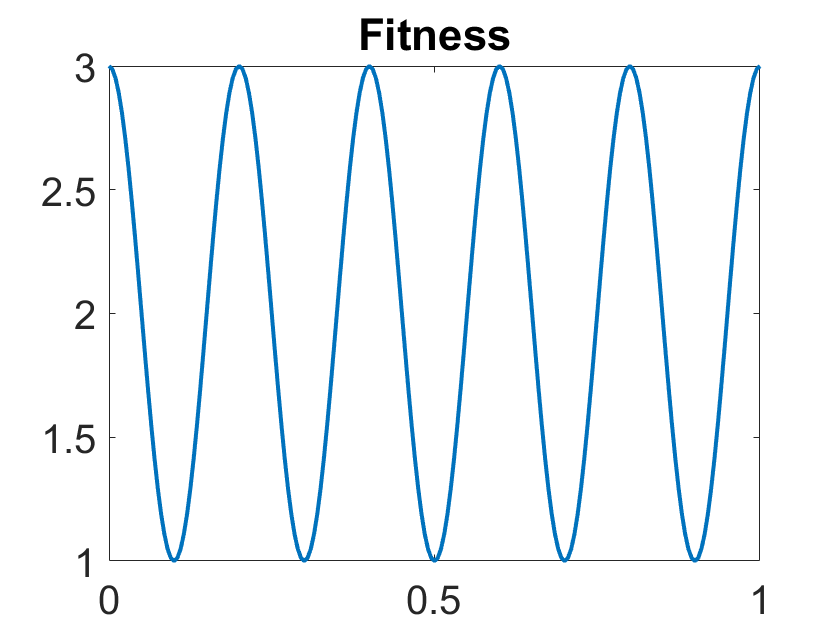


n_strats = 201;
strats = linspace(0,1,n_strats);
fitness = @(strats) (2+cos(10*pi*strats)); %.*arrayfun(@(x)indic(x,0.1,0.9),strats)+ ...
%arrayfun(@(x)indic(x,0,0.1),strats)+arrayfun(@(x)indic(x,0.9,1),strats);
figure
plot(strats, fitness(strats), 'LineWidth',2)
set(gca,"FontSize",20)
title("Fitness")


us = 0.01*(1:100);
tic
[max_eigs_high_freq, stable_dists_high_freq] =  compute_max_eigs(fitness, ...
    @(u,n_strats) flat_circ_spread_matrix(u, normal, n_strats), us, n_strats);
toc

Elapsed time is 3.551241 seconds.



nnz(arrayfun(@(i) max_eigs_high_freq(i+1) > max_eigs_high_freq(i), 1:(length(us)-1)))

ans = 41

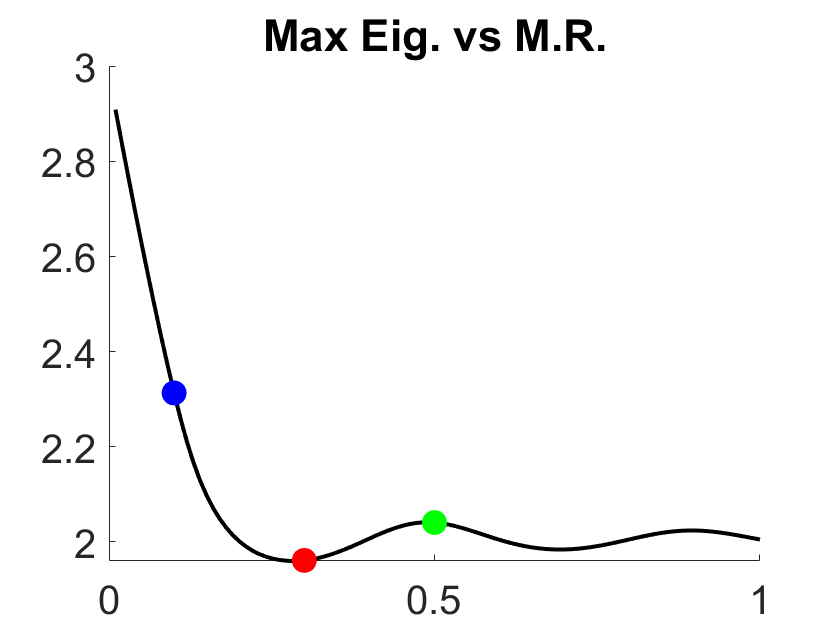


figure
hold on
plot(us, max_eigs_high_freq, 'k', "LineWidth", 2)
plot(us(10), max_eigs_high_freq(10), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 12)
plot(us(30), max_eigs_high_freq(30), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 12)
plot(us(50), max_eigs_high_freq(50), 'go', 'MarkerFaceColor', 'g', 'MarkerSize', 12)
hold off
set(gca,"FontSize",20)
title("Max Eig. vs M.R.")

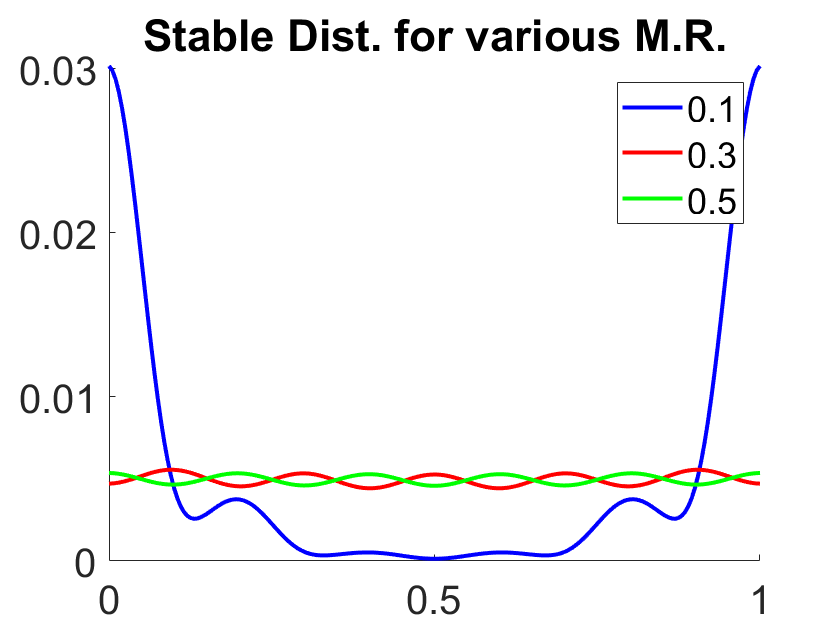


figure
hold on
plot(strats, stable_dists_high_freq(10,:), 'b', "LineWidth", 2);
plot(strats, stable_dists_high_freq(30,:), 'r', "LineWidth", 2);
plot(strats, stable_dists_high_freq(50,:), 'g', "LineWidth", 2);
title("Stable Dist. for various M.R.")
set(gca,"FontSize",20)
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

## DOESN'T work with normal spread?

n_strats = 101;
strats = linspace(0,1,n_strats);
fitness = @(strats) (2+cos(10*pi*strats)); %.*arrayfun(@(x)indic(x,0.1,0.9),strats)+ ...
%arrayfun(@(x)indic(x,0,0.1),strats)+arrayfun(@(x)indic(x,0.9,1),strats);
fitness = min_fit;
figure
plot(strats, fitness(strats), 'k')
title("Fitness")


us = 0.1*(20:50);
tic
[max_eigs_high_freq, stable_dists_high_freq] =  compute_max_eigs(fitness, ...
    @(u,n_strats) circ_spread_matrix(u, peak, n_strats), us, n_strats);
toc

Elapsed time is 0.309484 seconds.



nnz(arrayfun(@(i) max_eigs_high_freq(i+1) > max_eigs_high_freq(i), 1:(length(us)-1)))

ans = 19

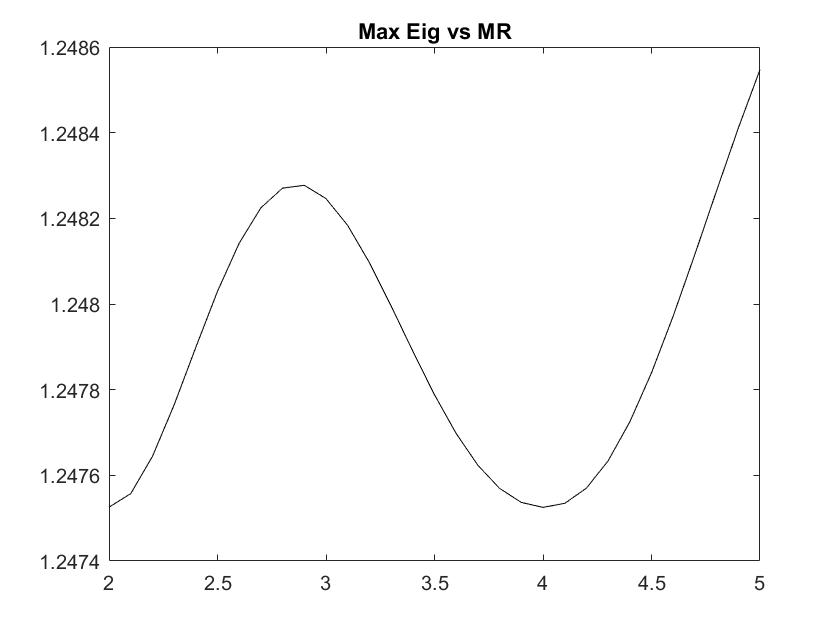

figure
plot(us,max_eigs_high_freq, 'k')
title("Max Eig vs MR")

## Still seeing local optimum for small MR, even with norm_circ

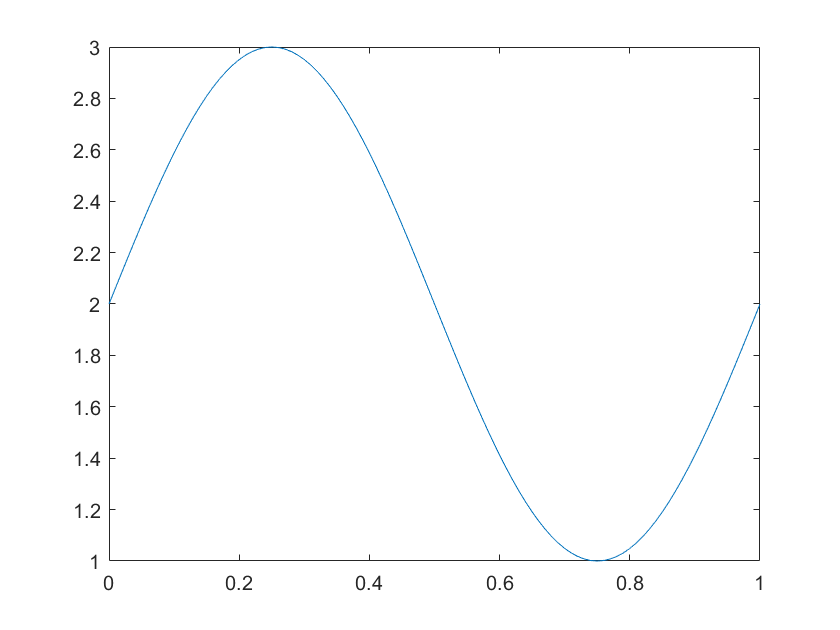

n_strats = 101;
strats = linspace(0,1,n_strats);
us = 0.001*(1:100);
fitness = @(strats) 2+sin(2*pi*(strats));
%fitness = @(strats) 2+sin(2*pi*(strats-0.25));
%fitness = @(strats) 2+cos(2*pi*(strats));

figure
plot(strats, fitness(strats))


tic
[max_eigs, stable_dists] =  compute_max_eigs(fitness, ...
    @(u,n_strats) norm_circ_spread_matrix(u, peak, n_strats), us, n_strats);
%@(u,n_strats) integ_circ_spread_matrix(u, peak, n_strats), us, n_strats);
toc

Elapsed time is 14.203669 seconds.


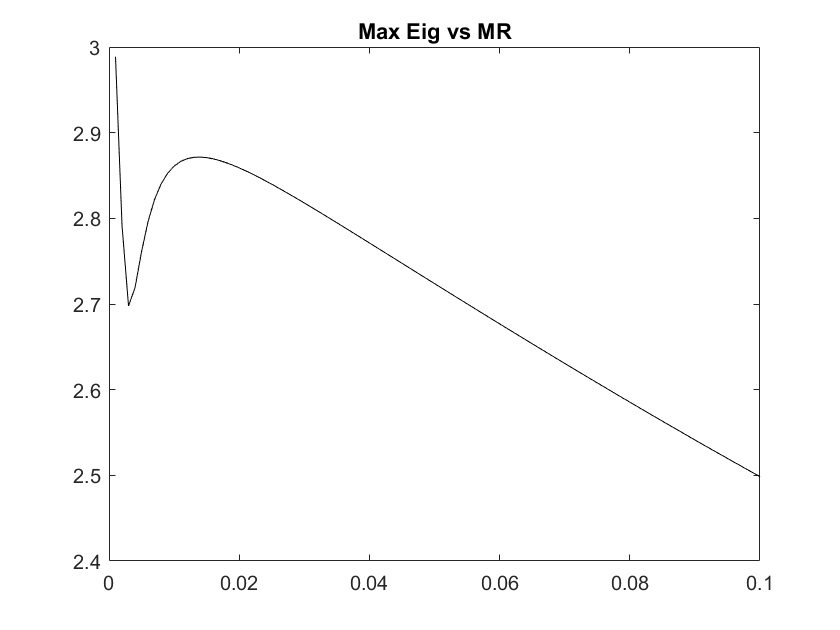


figure
plot(us, max_eigs, '-k')
title("Max Eig vs MR")

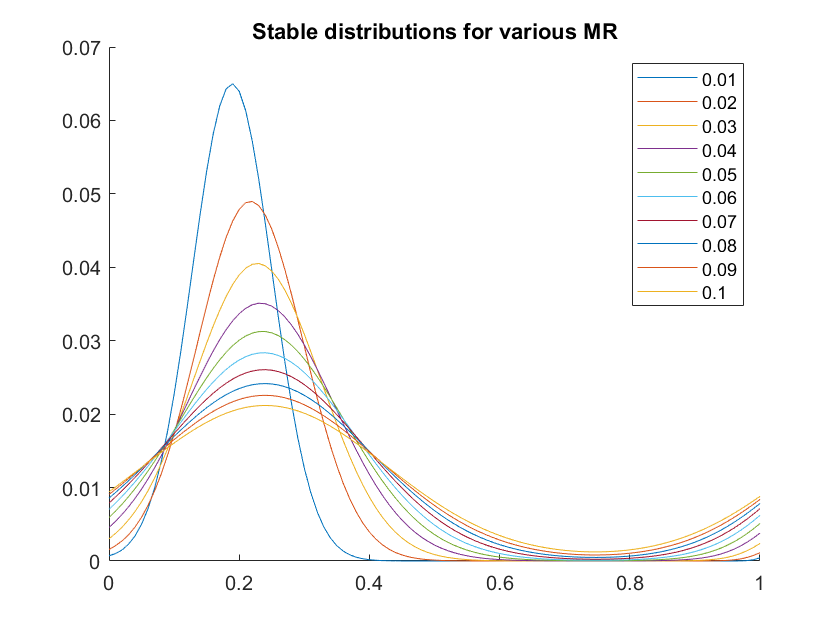


figure
hold on
n_plot = 10;
is = floor((1:n_plot)*length(us)/n_plot);
for i=1:length(is)
    plot(strats, stable_dists(is(i),:));
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

nnz(arrayfun(@(i) max_eigs(i+1) > max_eigs(i), 1:(length(us)-1)))

ans = 11

[a,b] = min(max_eigs)

a = 2.4985

b = 100

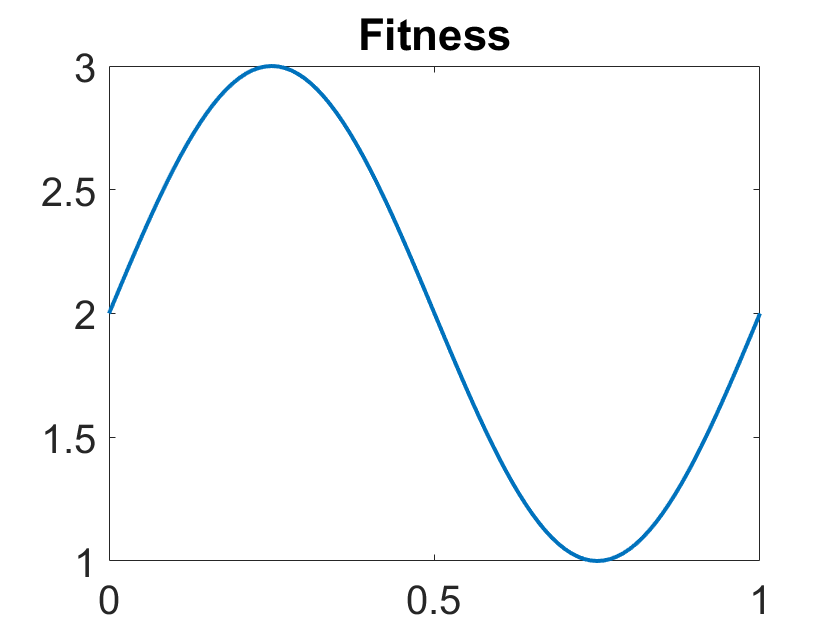

n_strats = 101;
strats = linspace(0,1,n_strats);
fitness = sin_fit;

figure
plot(strats, fitness(strats), 'LineWidth',2)
set(gca,"FontSize",20)
title("Fitness")


us = 0.001*(1:30);
ns = [51, 101, 251, 501];
max_eigs_record = zeros(length(ns), length(us));
for i=1:length(ns)
    tic
    if i == 1
        [max_eigs, stable_dists] =  compute_max_eigs(fitness, ...
    @(u,n_strats) norm_circ_spread_matrix(u, peak, n_strats), us, ns(i));
    else 
        [max_eigs, ~] =  compute_max_eigs(fitness, ...
    @(u,n_strats) norm_circ_spread_matrix(u, peak, n_strats), us, ns(i));
    end
    max_eigs_record(i,:) = max_eigs;
    toc
end

Elapsed time is 1.509682 seconds.
Elapsed time is 4.639985 seconds.
Elapsed time is 29.407374 seconds.
Elapsed time is 108.163222 seconds.


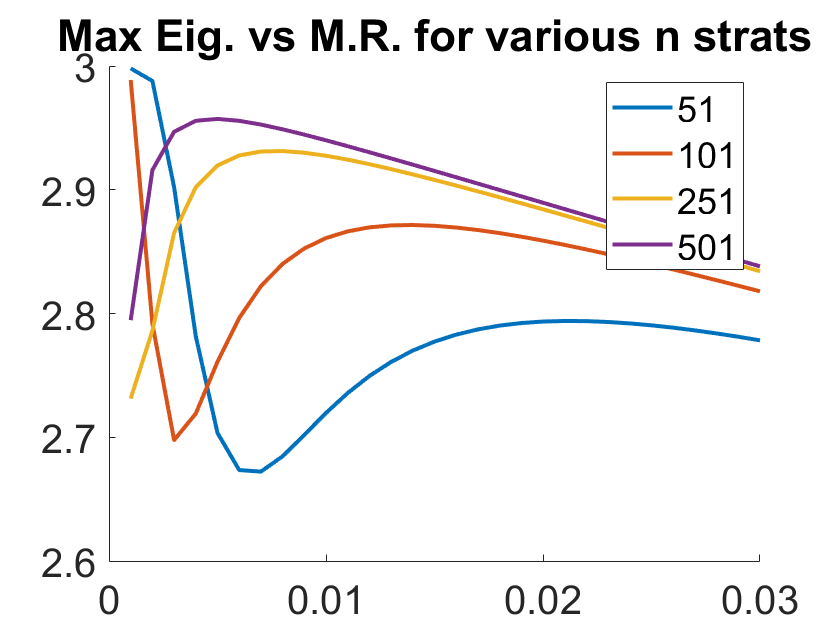


figure
hold on
for i=1:length(ns)
    plot(us, max_eigs_record(i,:), 'LineWidth',2)
end
title("Max Eig. vs M.R. for various n strats")
set(gca,"FontSize",20)
legend(arrayfun(@(u) num2str(u), ns, 'UniformOutput', false))
hold off

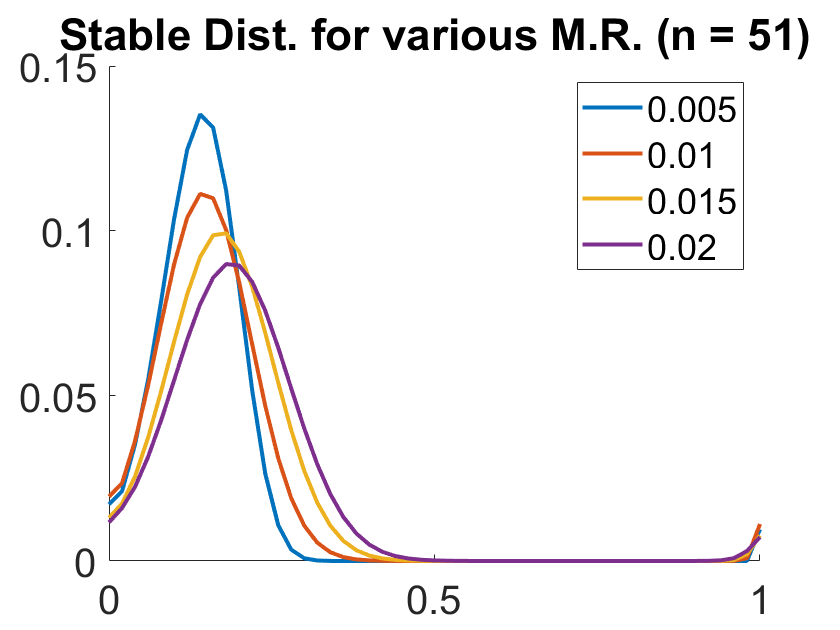


figure
hold on
is = [5, 10, 15, 20];
for i=1:length(is)
    plot(linspace(0,1,ns(1)), stable_dists(is(i),:), 'LineWidth', 2);
end
title("Stable Dist. for various M.R. (n = " + ns(1) + ")")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
set(gca,"FontSize",20)
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

## Upcurve for high MR disappears with better norm_circ

n_strats = 101;
strats = linspace(0,1,n_strats);
us = 0.01*(50:80);
tic
[max_eigs, stable_dists] =  compute_max_eigs(min_fit, ...
    @(u,n_strats) norm_circ_spread_matrix(u, normal, n_strats), us, n_strats);
    %@(u,n_strats) norm_circ_spread_matrix(u, normal, n_strats), us, n_strats);
toc

Elapsed time is 5.130967 seconds.


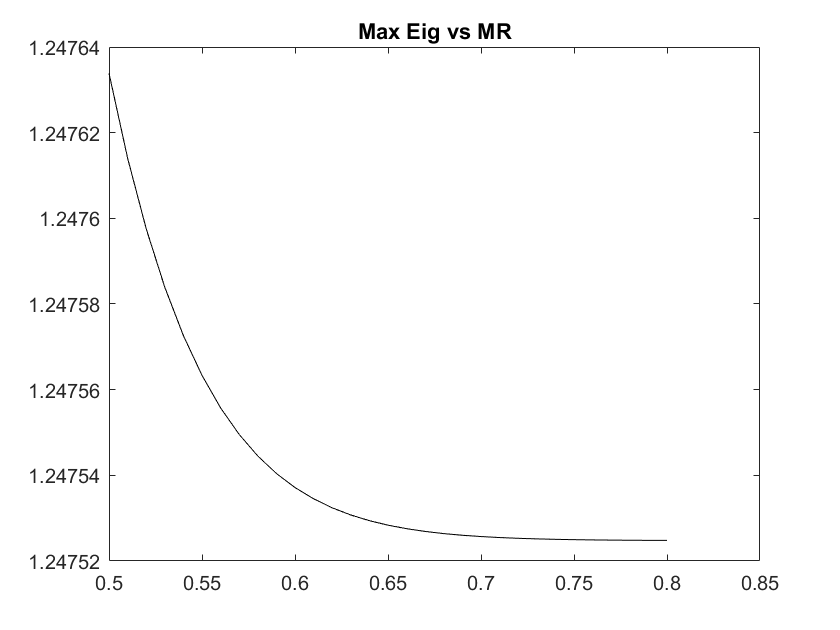


figure
plot(us, max_eigs, '-k')
title("Max Eig vs MR")

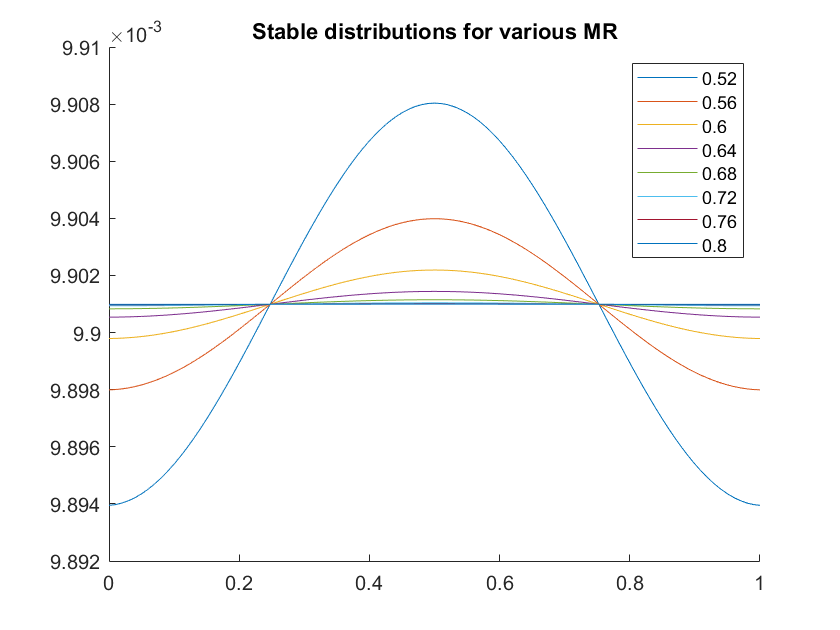


figure
hold on
n_plot = 8;
is = floor((1:n_plot)*length(us)/n_plot);
for i=1:length(is)
    plot(strats, stable_dists(is(i),:));
end
title("Stable distributions for various MR")
legend(arrayfun(@(u) num2str(u), us(is), 'UniformOutput', false))
%xlim([1/(n_strats-1),1-1/(n_strats-1)])
hold off

nnz(arrayfun(@(i) max_eigs(i+1) > max_eigs(i), 1:(length(us)-1)))

ans = 0

[a,b] = min(max_eigs)

a = 1.2475

b = 31

## Fitness is ignored for large MR

One explanation that could cover all these phenomenon is that for large MR, the fitness is effectively ignored, yielding a characteritic eignevector of the domain. When this is not uniform, some fitnesses will just so happen to exploit this better. 

n_strats = 101;
strats = linspace(0,1,n_strats);
us = linspace(0.1,1,10);
tic
[const_max_eigs, const_stable_dists] =  compute_max_eigs(const, ...
    @(u,n_strats) circ_spread_matrix(u, normal, n_strats), us, n_strats);
[cos_max_eigs, cos_stable_dists] =  compute_max_eigs(cos_fit, ...
    @(u,n_strats) circ_spread_matrix(u, normal, n_strats), us, n_strats);
[min_max_eigs, min_stable_dists] =  compute_max_eigs(min_fit, ...
    @(u,n_strats) circ_spread_matrix(u, normal, n_strats), us, n_strats);
toc

Elapsed time is 0.498343 seconds.


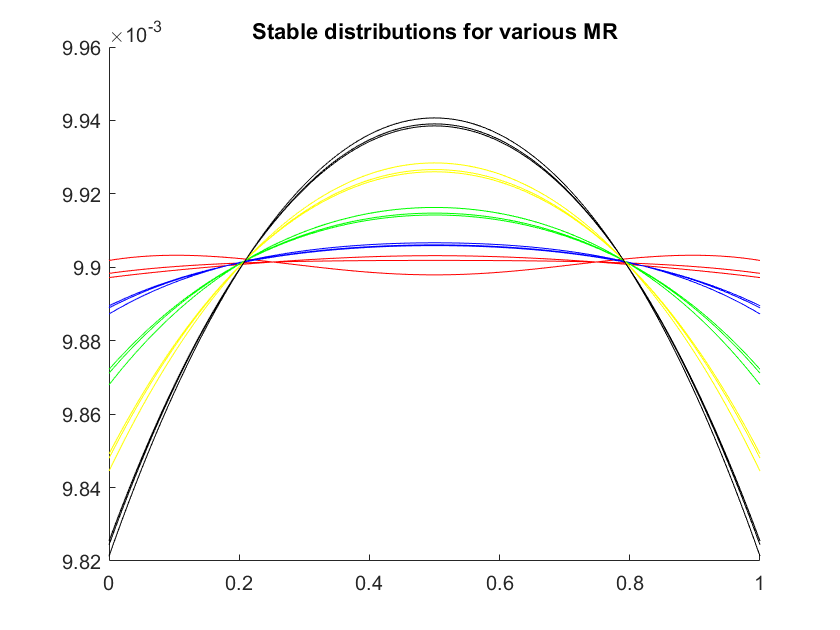


figure
hold on
colors = ['r', 'b', 'g', 'y', 'k', 'm'];
is = [6, 7, 8, 9, 10];
for i=1:length(is)
    plot(strats, const_stable_dists(is(i),:), colors(i));
    plot(strats, cos_stable_dists(is(i),:), colors(i));
    plot(strats, min_stable_dists(is(i),:), colors(i));
end
title("Stable distributions for various MR")
hold off

## Checking in another domain

n_strats = 101;
strats = linspace(0,1,n_strats);
us = linspace(0.1,1,10);
spread_funct = @(u,n_strats) integ_trunc_spread_matrix(u, normal, n_strats);
tic
[const_max_eigs, const_stable_dists] =  compute_max_eigs(const, spread_funct, us, n_strats);
[cos_max_eigs, cos_stable_dists] =  compute_max_eigs(cos_fit, spread_funct, us, n_strats);
[min_max_eigs, min_stable_dists] =  compute_max_eigs(min_fit, spread_funct, us, n_strats);
toc

Elapsed time is 49.523777 seconds.


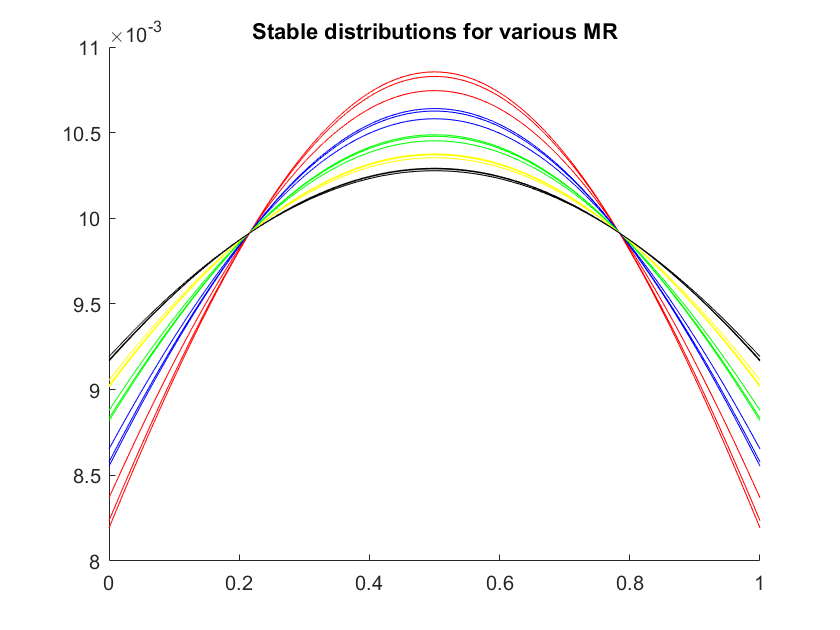


figure
hold on
colors = ['r', 'b', 'g', 'y', 'k', 'm'];
is = [6, 7, 8, 9, 10];
for i=1:length(is)
    plot(strats, const_stable_dists(is(i),:), colors(i));
    plot(strats, cos_stable_dists(is(i),:), colors(i));
    plot(strats, min_stable_dists(is(i),:), colors(i));
end
title("Stable distributions for various MR")
hold off

## Functions

This block needs to be run first (Matlab won't let functions be defined at the beginning, and its nice to have them in the same file). 

function spread = trunc_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        spread(r,:) = spread_funct(strats, strats(r), u);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = accum_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % evaluate the spread function at 1/n spacing, and group values beyond boundary
        vals = spread_funct(linspace(-5,6,11*n), strats(r), u);
        spread(r,:) = vals(1,(5*n+1):6*n); 
        spread(r,1) = spread(r,1) + sum(vals(1, 1:5*n));
        spread(r,n) = spread(r,n) + sum(vals(1, (6*n+1):11*n));

        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = circ_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n
        vals = spread_funct(linspace(-2,3,5*n), strats(r), u);
        spread(r,:) = vals(1:n) + vals((n+1):2*n) + vals((2*n+1):3*n) + ...
            vals((3*n+1):4*n) + vals((4*n+1):5*n);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = unif_spread_matrix(u,~,n)
    spread = (1-u)*eye(n) + (u/n)*ones(n, n);
end

function spread = flat_circ_spread_matrix(u,~,n)
    spread = eye(n);
    spacing = 1/(n-1); % space between closest traits
    num_left = round((u/2)/spacing); % number of traits reached to the left
    for r=1:n
        spread(r,r) = 1;
        for j=1:num_left
            spread(r,mod(r-1+j,n)+1) = spread(r,mod(r-1+j,n)+1) + 1;
            spread(r,mod(r-1-j,n)+1) = spread(r,mod(r-1-j,n)+1) + 1;
        end
        %spread(r,mod(r-1-num_left:r-1+num_left,n)+1) = 1/(2*num_left+1);
        spread(r,:) = spread(r,:) / sum(spread(r,:));
    end
    spread = spread';
end

function spread = norm_circ_spread_matrix(u,~,n)
    strats = linspace(0,1,n); 
    spread = zeros(n,n);
    extended = linspace(-7,8,15*n); % should be valid to u=1
    for r=1:n
        cdf = @(x) (1+erf((x-strats(r))/(u*sqrt(2))))/2;
        for c=2:(length(extended)-1)
            spread(r,mod(c-1,n)+1) = spread(r,mod(c-1,n)+1) + ...
    cdf((extended(c)+extended(c-1))/2)-cdf((extended(c)+extended(c+1))/2);
        end
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_accum_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -5, (strats(1)+strats(2))/2);
        for c=2:(n-1)
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 6);
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_trunc_spread_matrix(u, spread_funct, n) % takes much longer
    strats = linspace(0,1,n);   
    spread = zeros(n,n);
    for r=1:n % integrate between midpoints of discretization
        spread(r,1) = integral(@(x) spread_funct(x, strats(r), u), ...
                -1/(2*(n-1)), (strats(1)+strats(2))/2);
        for c=2:(n-1) % bin for enpoints goes beyond 0,1 so they are as wide as the others
            spread(r,c) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(c)+strats(c-1))/2, (strats(c)+strats(c+1))/2);
        end
        spread(r,n) = integral(@(x) spread_funct(x, strats(r), u), ...
                (strats(n-1)+strats(n))/2, 1+1/(2*(n-1)));
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function spread = integ_circ_spread_matrix(u, spread_funct, n)
    strats = linspace(0,1,n); 
    spread = zeros(n,n);
    extended = linspace(-2,3,5*n);
    for r=1:n % evaluate the spread function at 1/n spacing, and group values beyond boundary
        for c=2:(5*n-1)
            spread(r,mod(c,n)+1) = spread(r,mod(c,n)+1) + integral(@(x) ...
                spread_funct(x, strats(r), u), ...
                (extended(c)+extended(c-1))/2, (extended(c)+extended(c+1))/2);
        end
        spread(r,:) = spread(r,:)/sum(spread(r,:)); % normalize
    end
    spread = spread';
end

function [max_eigs, stable_dists] = compute_max_eigs(fitness,spread_matrix_funct,us,n_strats)
    max_eigs = zeros(1,length(us));
    stable_dists = zeros(length(us), n_strats);
    
    growth = zeros(n_strats,n_strats);
    growth(sub2ind(size(growth), 1:n_strats, 1:n_strats)) = fitness(linspace(0,1,n_strats));
    for i=1:length(us)
        A = spread_matrix_funct(us(i), n_strats)*growth;
        [V,D] = eig(A);
        [max_eig, loc] = max(diag(D));
        max_eigs(i) = max_eig;
        stable_dist = abs(V(:,loc))/sum(abs(V(:,loc)));
        stable_dists(i,:) = stable_dist;
    end
end